# Dummy-coded maps for stimulus modulated expectation ratings

Model (CESeO)

- parameter: 

-     0 **C**ue onset 

-     0 **E**xpectationRating onset 

-     0 **S**timulus onset 

-     1          pmod: **e**xpectation rating (angle)

-     0 **O**utcomeRating onset

- Motion covariate: 24DOF + CSF

- Spike combined into one regressor (Incorrect)

# Pain modulated w/ expectation ratings (dummy coded; painXexpectation > rest)

#### Pain x Expectation :: load dataset

clear all;
close all;
mount_dir = '/Volumes/spacetop_projects_cue/analysis/fmri/spm/univariate/model02_CESeO/1stLevel';
con_list = dir(fullfile(mount_dir, '*/con_0019.nii'));
spm('Defaults','fMRI') 
con_fldr = {con_list.folder}; fname = {con_list.name};
con_files = strcat(con_fldr,'/', fname)';
con_data_obj = fmri_data(con_files);

Using default mask: /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/brainmask_canlab.nii
Direct calls to spm_defauts are deprecated.
Please use spm('Defaults',modality) or spm_get_defaults instead.


sampleto = '/Volumes/spacetop_projects_cue/analysis/fmri/spm/univariate/model02_CESeO/1stLevel/sub-0014/con_0019.nii'

loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 29951100 bytes
Loading image number:    75
Elapsed time is 9.890122 seconds.
Image names entered, but fullpath attribute is empty. Getting path info.
Number of unique values in dataset: 7217384  Bit rate: 22.78 bits


contrast_name = {'cue_P', 'cue_V', 'cue_C', 'cue_G',...
    'stim_P', 'stim_V', 'stim_C', 'stim_G',...
    'stimXexpect_P', 'stimXexpect_V', 'stimXexpect_C',...
    'motor', ...
    'simple_cue_P', 'simple_cue_V', 'simple_cue_C', ...
    'simple_stim_P', 'simple_stim_V', 'simple_stim_C',...
    'simple_stimXexpect_P', 'simple_stimXexpect_V', 'simple_stimXexpect_C'};


#### Pain x Expectation :: `check data coverage`

m = mean(con_data_obj);
m.dat = sum(~isnan(con_data_obj.dat) & con_data_obj.dat ~= 0, 2);
orthviews(m, 'trans'); % display

SPM12: spm_check_registration (v7759)              18:56:36 - 12/01/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1


Grouping contiguous voxels:   1 regions


#### Pain x Expectation :: Plot diagnostics, before l2norm

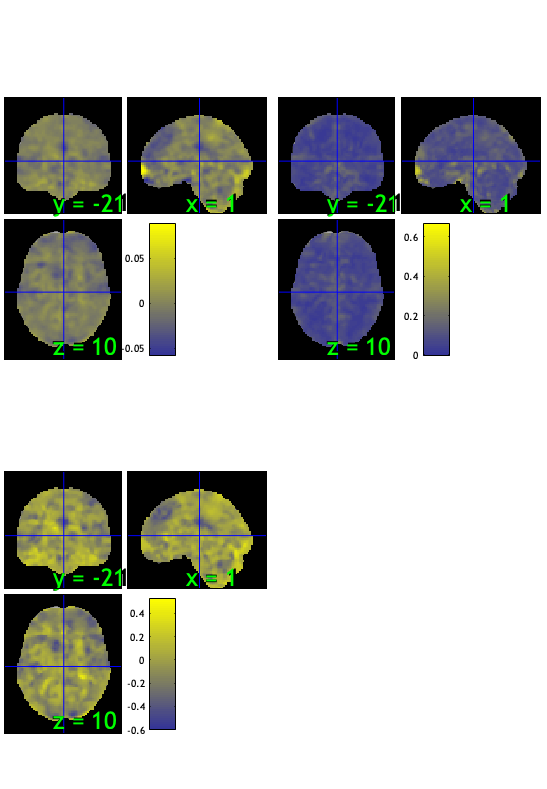

______________________________________________________________
Outlier analysis
______________________________________________________________
global mean | global mean to var | spatial MAD | Missing values |   0 images 


Retained 4 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 13.33%
Expected 3.75 outside 95% ellipsoid, found   5

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 3 images		Cases 36 37 48 
Uncorrected: 5 images		Cases 20 36 37 48 70 

Retained 10 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 58.67%
Expected 3.75 outside 95% ellipsoid, found   0

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 0 images		Cases  
Uncorrected: 0 images		Cases  

Mahalanobis (cov and corr, q<0.05 corrected):
  3 images 
                               Outlier_count    Percentage
                               

SPM12: spm_check_registration (v7759)              18:57:07 - 12/01/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1
 (all)  

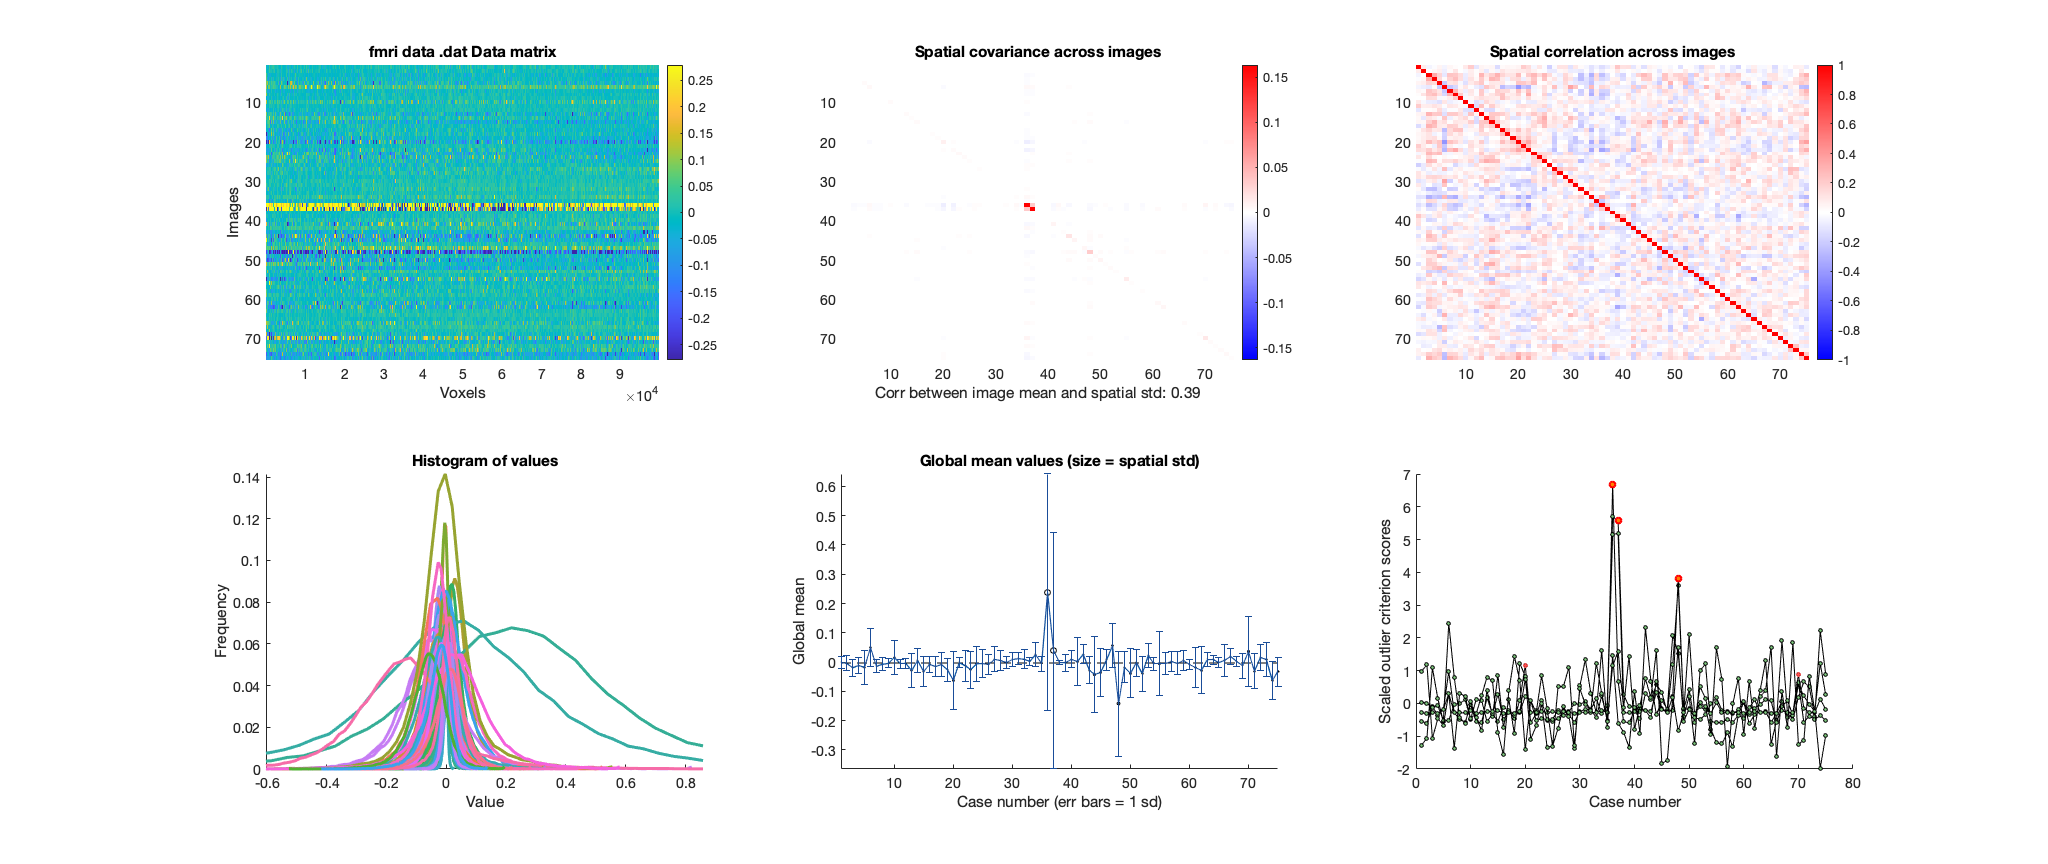

Grouping contiguous voxels:   1 regions


Grouping contiguous voxels:   1 regions


Grouping contiguous voxels:   1 regions


drawnow; snapnow

[wh_outlier_uncorr, wh_outlier_corr] = plot(con_data_obj);

#### Pain x Expectation :: run robfit

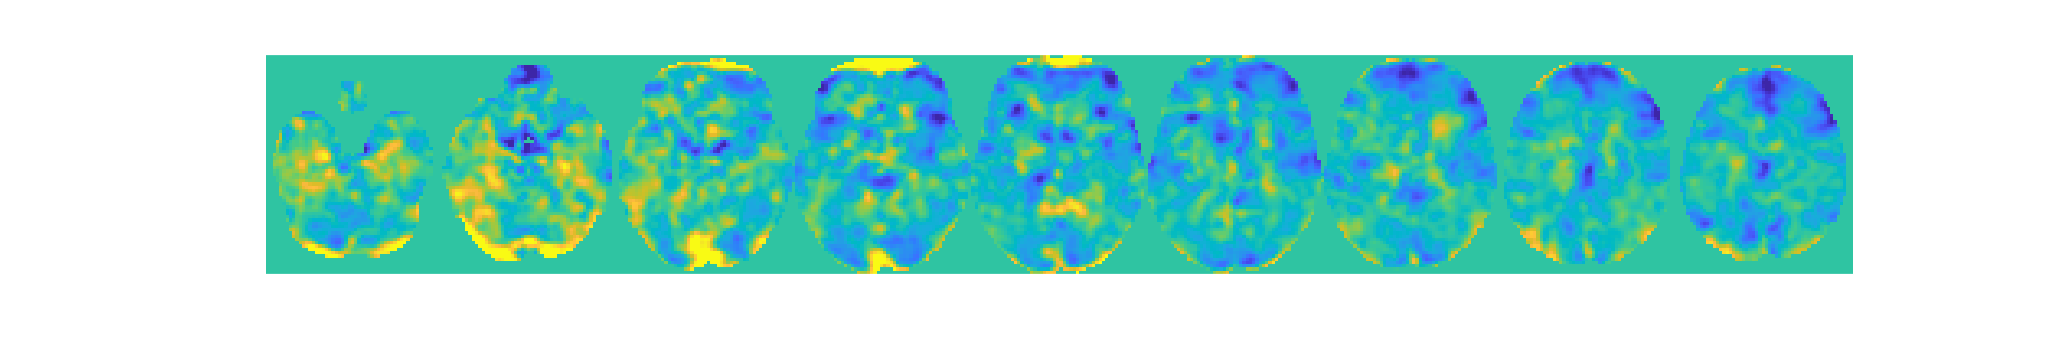

set(gcf,'Visible','on');

figure ('Visible', 'on');
drawnow, snapnow;


#### Pain x Expectation :: remove outliers based on plot

con = con_data_obj;
disp(strcat("current length is ", num2str(size(con_data_obj.dat,2))));

current length is 75


%for s = 1:length(wh_outlier_corr)
    %disp(strcat("-------subject", num2str(s), "------"))
con.dat = con_data_obj.dat(:,~wh_outlier_corr);
con.image_names = con_data_obj.image_names(~wh_outlier_corr,:);
con.fullpath = con_data_obj.fullpath(~wh_outlier_corr,:);
con.files_exist = con_data_obj.files_exist(~wh_outlier_corr,:);
%end
disp(strcat("after removing ", num2str(sum(wh_outlier_corr)), " participants, size is now ",num2str(size(con.dat,2))));

after removing 3 participants, size is now 72


[path,n,e] = fileparts(con_fldr(wh_outlier_corr));
disp(strcat("participants that are outliers:... ", n));

    "participants that are outliers:... sub-0073"    "participants that are outliers:... sub-0074"    "participants that are outliers:... sub-0091"



disp(n);

    {'sub-0073'}    {'sub-0074'}    {'sub-0091'}



#### Pain x Expectation :: plot diagnostics, after l2norm

imgs2 = con.rescale('l2norm_images');

#### Pain x Expectation :: ttest

t = ttest(imgs2);

One-sample t-test
Calculating t-statistics and p-values


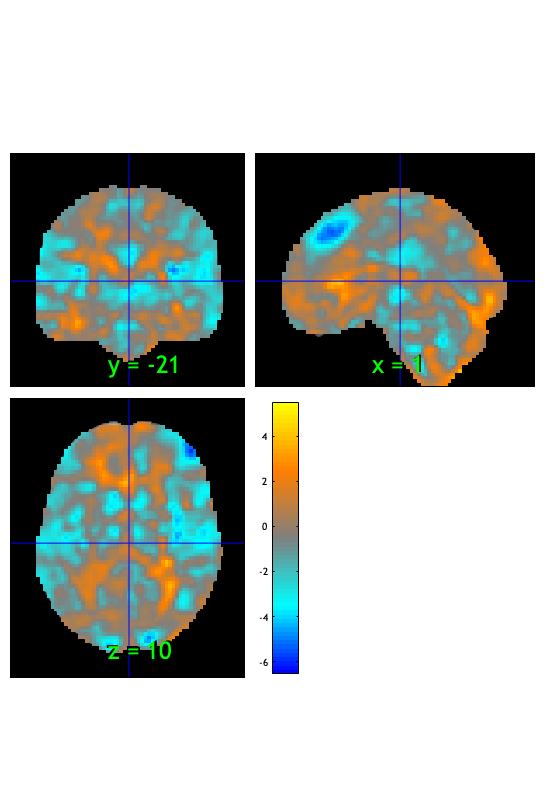

SPM12: spm_check_registration (v7759)              18:57:13 - 12/01/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1


orthviews(t);

drawnow, snapnow;

fdr_t = threshold(t, .05, 'fdr');

Image   1 FDR q < 0.050 threshold is 0.004471

Image   1
116 contig. clusters, sizes   1 to 2550
Positive effect: 593 voxels, min p-value: 0.00000072
Negative effect: 8337 voxels, min p-value: 0.00000000


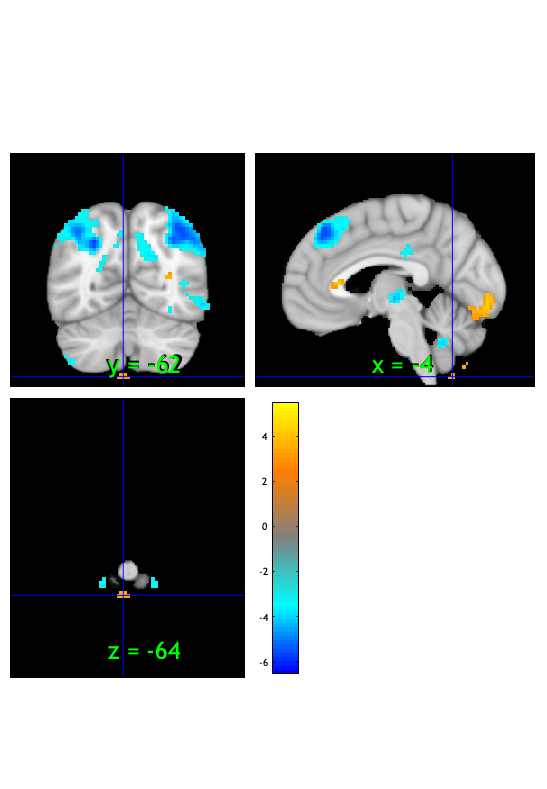

SPM12: spm_check_registration (v7759)              18:57:15 - 12/01/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1


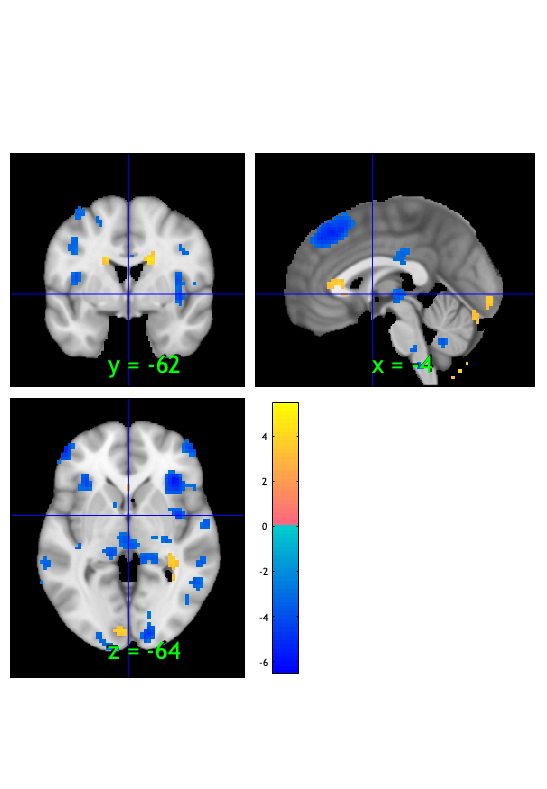

orthviews(fdr_t);

drawnow, snapnow;

create_figure('montage'); axis off;
montage(fdr_t);

Setting up fmridisplay objects


sagittal montage: 142 voxels displayed, 8788 not displayed on these slices


sagittal montage: 209 voxels displayed, 8721 not displayed on these slices


sagittal montage: 147 voxels displayed, 8783 not displayed on these slices


axial montage: 1647 voxels displayed, 7283 not displayed on these slices


axial montage: 1867 voxels displayed, 7063 not displayed on these slices


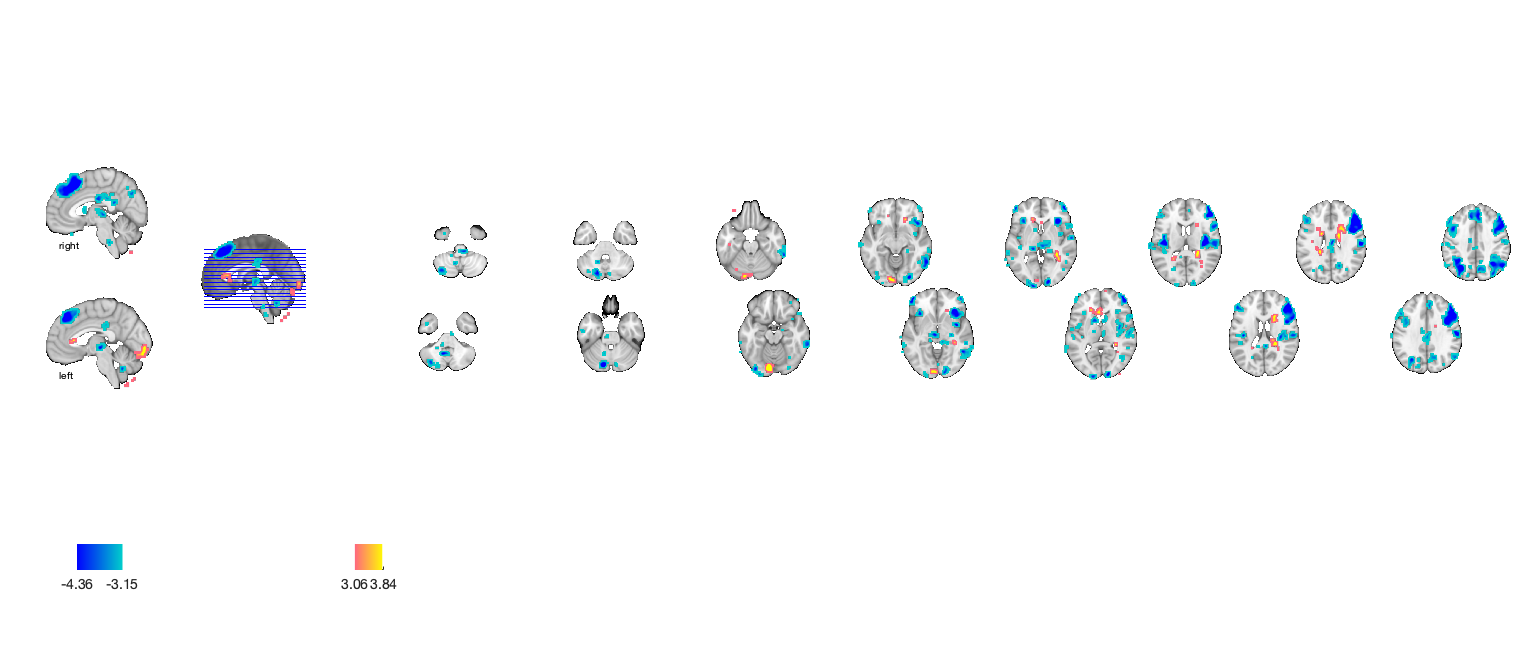

drawnow, snapnow;

#### Pain x Expectation :: Neurosynth similarity

[image_by_feature_correlations, top_feature_tables] = neurosynth_feature_labels( mean(imgs2), 'images_are_replicates', false, 'noverbose');

Input image 1
fullpath_was_empty
_____________________________________________________________________
    testr_low       words_low       testr_high      words_high  
    _________    _______________    __________    ______________

    -0.20503     {'counting'   }     0.18719      {'images'    }
    -0.20061     {'calculation'}     0.17035      {'animal'    }
    -0.19181     {'solving'    }     0.15629      {'age'       }
    -0.18351     {'numerical'  }     0.15384      {'male'      }
    -0.18047     {'1back'      }     0.15118      {'trait'     }
    -0.17145     {'arithmetic' }     0.14591      {'depression'}
    -0.16381     {'numbers'    }     0.13763      {'loss'      }
    -0.16346     {'load'       }     0.13203      {'expression'}
    -0.16098     {'rule'       }     0.12554      {'approach'  }
     -0.1579     {'card'       }     0.12406 

% [image_by_feature_correlations, top_feature_tables] = neurosynth_feature_labels( m, 'images_are_replicates', false, 'noverbose');

**Pain x Expectation :: Pattern Phil**

[obj, names] = load_image_set('pain_cog_emo');

Loaded images:
/Users/h/Documents/MATLAB/CanlabCore/CanlabCore/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_pMCC_Pain.nii
/Users/h/Documents/MATLAB/CanlabCore/CanlabCore/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_aMCC_Pain.nii
/Users/h/Documents/MATLAB/CanlabCore/CanlabCore/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_pACC_Pain.nii
/Users/h/Documents/MATLAB/CanlabCore/CanlabCore/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_sgACC_Pain.nii
/Users/h/Documents/MATLAB/CanlabCore/CanlabCore/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_vmPFC_Pain.nii
/Users/h/Documents/MATLAB/CanlabCore/CanlabCore/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_dMFC_Pain.nii
/Users/h/Documents/MATLAB/Can

bpls_wholebrain = get_wh_image(obj, [8 16 24]);
names_wholebrain = names([8 16 24]);
create_figure('Kragel Pain-Cog-Emo maps', 1, 3);

stats = image_similarity_plot(imgs2, 'average', 'mapset', bpls_wholebrain, 'networknames', names_wholebrain, 'nofigure');

Table of correlations Group:1
--------------------------------------
T-test on Fisher's r to Z transformed point-biserial correlations
 	R_avg	T	P	sig	
Pain Wholebrain	-0.0101	-1.3935	0.1678	0.0000	
Cog Wholebrain	0.0154	3.5480	0.0007	1.0000	
Emo Wholebrain	-0.0042	-0.6468	0.5198	0.0000	
 


axis image

subplot(1, 3, 2)

barplot_columns(stats.r', 'nofigure', 'colors', {[1 .9 0] [.2 .2 1] [1 .2 .2]}, 'names', names_wholebrain)

Col   1: Pain Wholebrain	Col   2: Cog Wholebrain	Col   3: Emo Wholebrain	
---------------------------------------------
Tests of column means against zero
---------------------------------------------
           Name            Mean_Value    Std_Error       T            P         Cohens_d 
    ___________________    __________    _________    ________    __________    _________

    {'Pain Wholebrain'}    -0.010058     0.0072395     -1.3893       0.16907     -0.16374
    {'Cog Wholebrain' }     0.015373      0.004332      3.5487    0.00069114      0.41822
    {'Emo Wholebrain' }    -0.004222     0.0064807    -0.65148       0.51684    -0.076777



ans = struct with fields:
         fig_han: [1×1 struct]
        axis_han: [1×1 Axes]
        bar_han1: [1×1 Bar]
         bar_han: {[1×1 Bar]  [1×1 Bar]  [1×1 Bar]}
    errorbar_han: {[1×1 ErrorBar]  [1×1 ErrorBar]  [1×1 ErrorBar]}
      point_han1: {72×3 cell}
        text_han: {72×3 cell}
       point_han: {72×3 cell}
    star_handles: [9.0013 10.0013 11.0013]


set(gca, 'FontSize', 14)
ylabel('Pattern similarity (r)');
title('Similarity (r) with patterns')

test_data_obj = resample_space(imgs2, bpls_wholebrain);

clear csim
for i = 1:3

    csim(:, i) = canlab_pattern_similarity(test_data_obj.dat, bpls_wholebrain.dat(:, i), 'cosine_similarity');

end

Number of zero or NaN values within weight mask, by input image:
297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 
Number of zero or NaN values within weight mask, by input image:
297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 
Warnin


subplot(1, 3, 3)

barplot_columns(csim, 'nofigure', 'colors', {[1 .9 0] [.2 .2 1] [1 .2 .2]}, 'names', names_wholebrain)

Col   1: Pain Wholebrain	Col   2: Cog Wholebrain	Col   3: Emo Wholebrain	
---------------------------------------------
Tests of column means against zero
---------------------------------------------
           Name            Mean_Value    Std_Error       T            P        Cohens_d 
    ___________________    __________    _________    ________    _________    _________

    {'Pain Wholebrain'}    -0.0097923    0.0072831     -1.3445      0.18306     -0.15845
    {'Cog Wholebrain' }      0.014306    0.0041202      3.4722    0.0008828      0.40921
    {'Emo Wholebrain' }      -0.00378    0.0065278    -0.57907      0.56437    -0.068244



ans = struct with fields:
         fig_han: [1×1 struct]
        axis_han: [1×1 Axes]
        bar_han1: [1×1 Bar]
         bar_han: {[1×1 Bar]  [1×1 Bar]  [1×1 Bar]}
    errorbar_han: {[1×1 ErrorBar]  [1×1 ErrorBar]  [1×1 ErrorBar]}
      point_han1: {72×3 cell}
        text_han: {72×3 cell}
       point_han: {72×3 cell}
    star_handles: [12.0013 13.0013 14.0013]


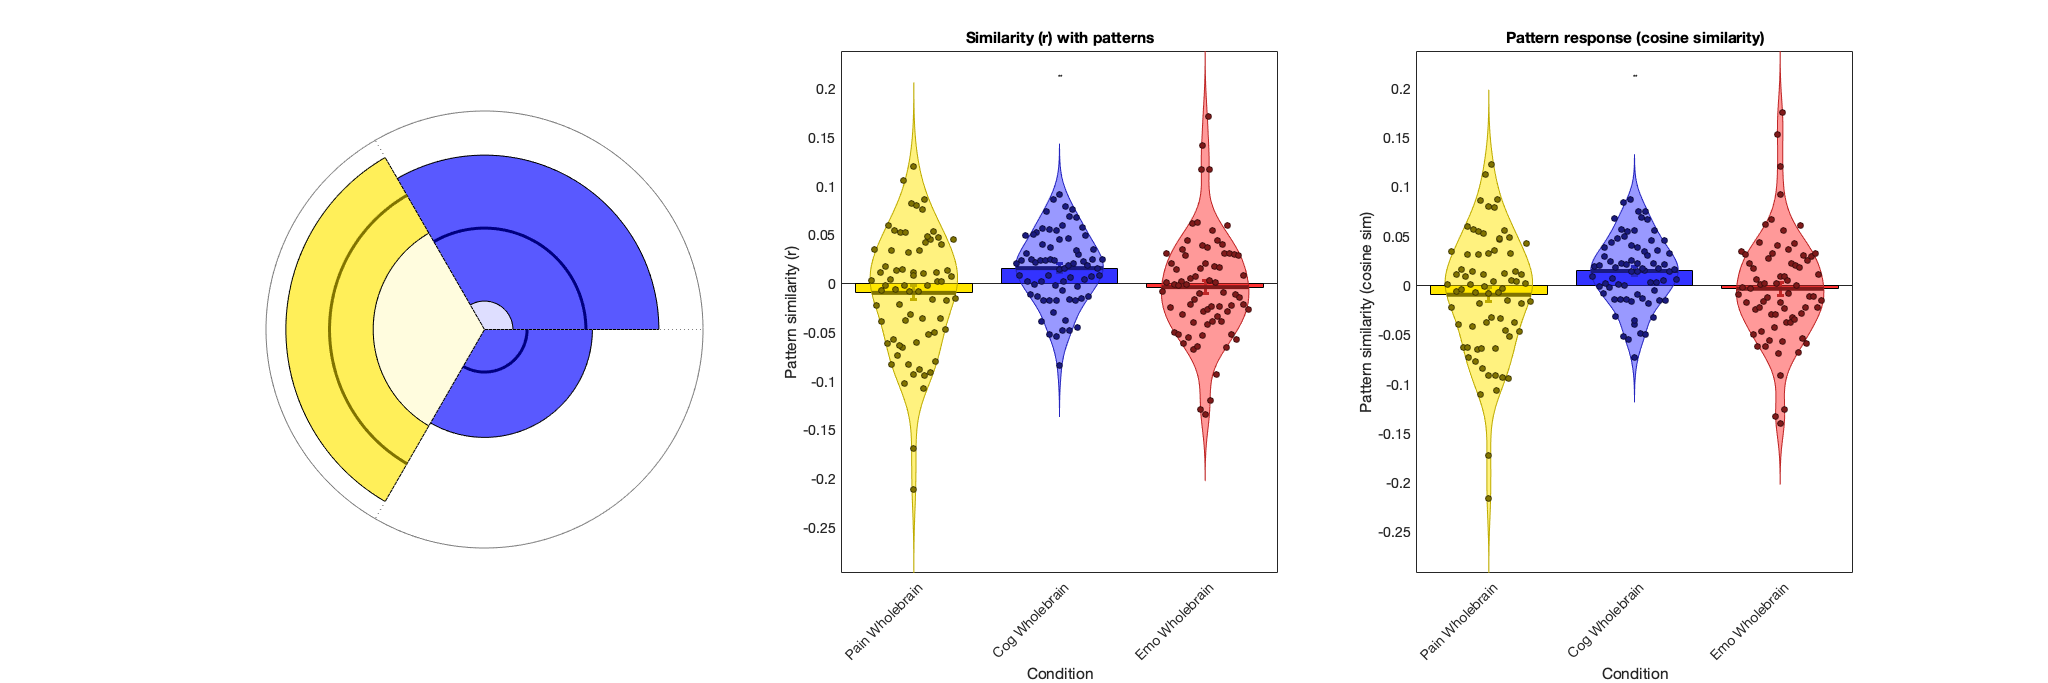

set(gca, 'FontSize', 14)
ylabel('Pattern similarity (cosine sim)');
title('Pattern response (cosine similarity)')

# Vicarious modulated w/ expectation ratings (dummy coded; vicariousXexpectation > rest)

clear all;
close all;

#### Vicarious x Expectation :: load dataset

mount_dir = '/Volumes/spacetop_projects_cue/analysis/fmri/spm/univariate/model02_CESeO/1stLevel';
con_list = dir(fullfile(mount_dir, '*/con_0020.nii'));
spm('Defaults','fMRI'); 
con_fldr = {con_list.folder}; fname = {con_list.name};
con_files = strcat(con_fldr,'/', fname)';
con_data_obj = fmri_data(con_files);

Using default mask: /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/brainmask_canlab.nii
Direct calls to spm_defauts are deprecated.
Please use spm('Defaults',modality) or spm_get_defaults instead.


sampleto = '/Volumes/spacetop_projects_cue/analysis/fmri/spm/univariate/model02_CESeO/1stLevel/sub-0014/con_0020.nii'

loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 29951100 bytes
Loading image number:    75
Elapsed time is 11.683513 seconds.
Image names entered, but fullpath attribute is empty. Getting path info.
Number of unique values in dataset: 7198853  Bit rate: 22.78 bits


contrast_name = {'cue_P', 'cue_V', 'cue_C', 'cue_G',...
    'stim_P', 'stim_V', 'stim_C', 'stim_G',...
    'stimXexpect_P', 'stimXexpect_V', 'stimXexpect_C',...
    'motor', ...
    'simple_cue_P', 'simple_cue_V', 'simple_cue_C', ...
    'simple_stim_P', 'simple_stim_V', 'simple_stim_C',...
    'simple_stimXexpect_P', 'simple_stimXexpect_V', 'simple_stimXexpect_C'};


#### Vicarious x Expectation :: `check data coverage`

m = mean(con_data_obj);
m.dat = sum(~isnan(con_data_obj.dat) & con_data_obj.dat ~= 0, 2);
orthviews(m, 'trans') % display

SPM12: spm_check_registration (v7759)              18:50:18 - 12/01/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1


Grouping contiguous voxels:   1 regions


ans = 1×1 cell array
    {1×1 region}


#### Vicarious x Expectation :: Plot diagnostics, before l2norm

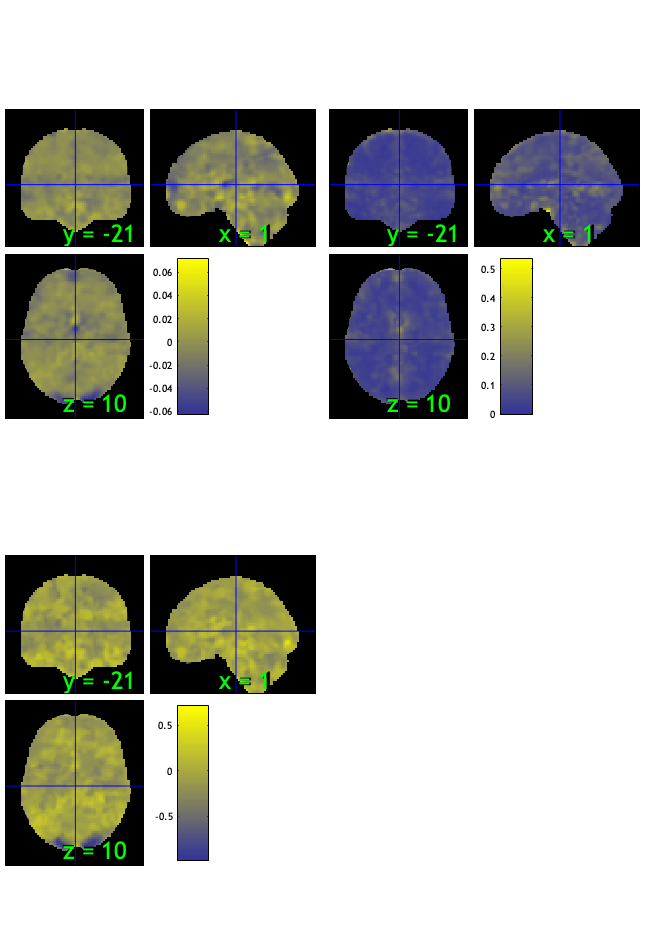

______________________________________________________________
Outlier analysis
______________________________________________________________
global mean | global mean to var | spatial MAD | Missing values |   0 images 


Retained 5 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 16.00%
Expected 3.75 outside 95% ellipsoid, found   6

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 4 images		Cases 36 37 43 44 
Uncorrected: 6 images		Cases 36 37 43 44 48 52 

Retained 7 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 54.67%
Expected 3.75 outside 95% ellipsoid, found   0

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 0 images		Cases  
Uncorrected: 0 images		Cases  

Mahalanobis (cov and corr, q<0.05 corrected):
  4 images 
                               Outlier_count    Percentage
                               

SPM12: spm_check_registration (v7759)              18:50:53 - 12/01/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1
 (all)  

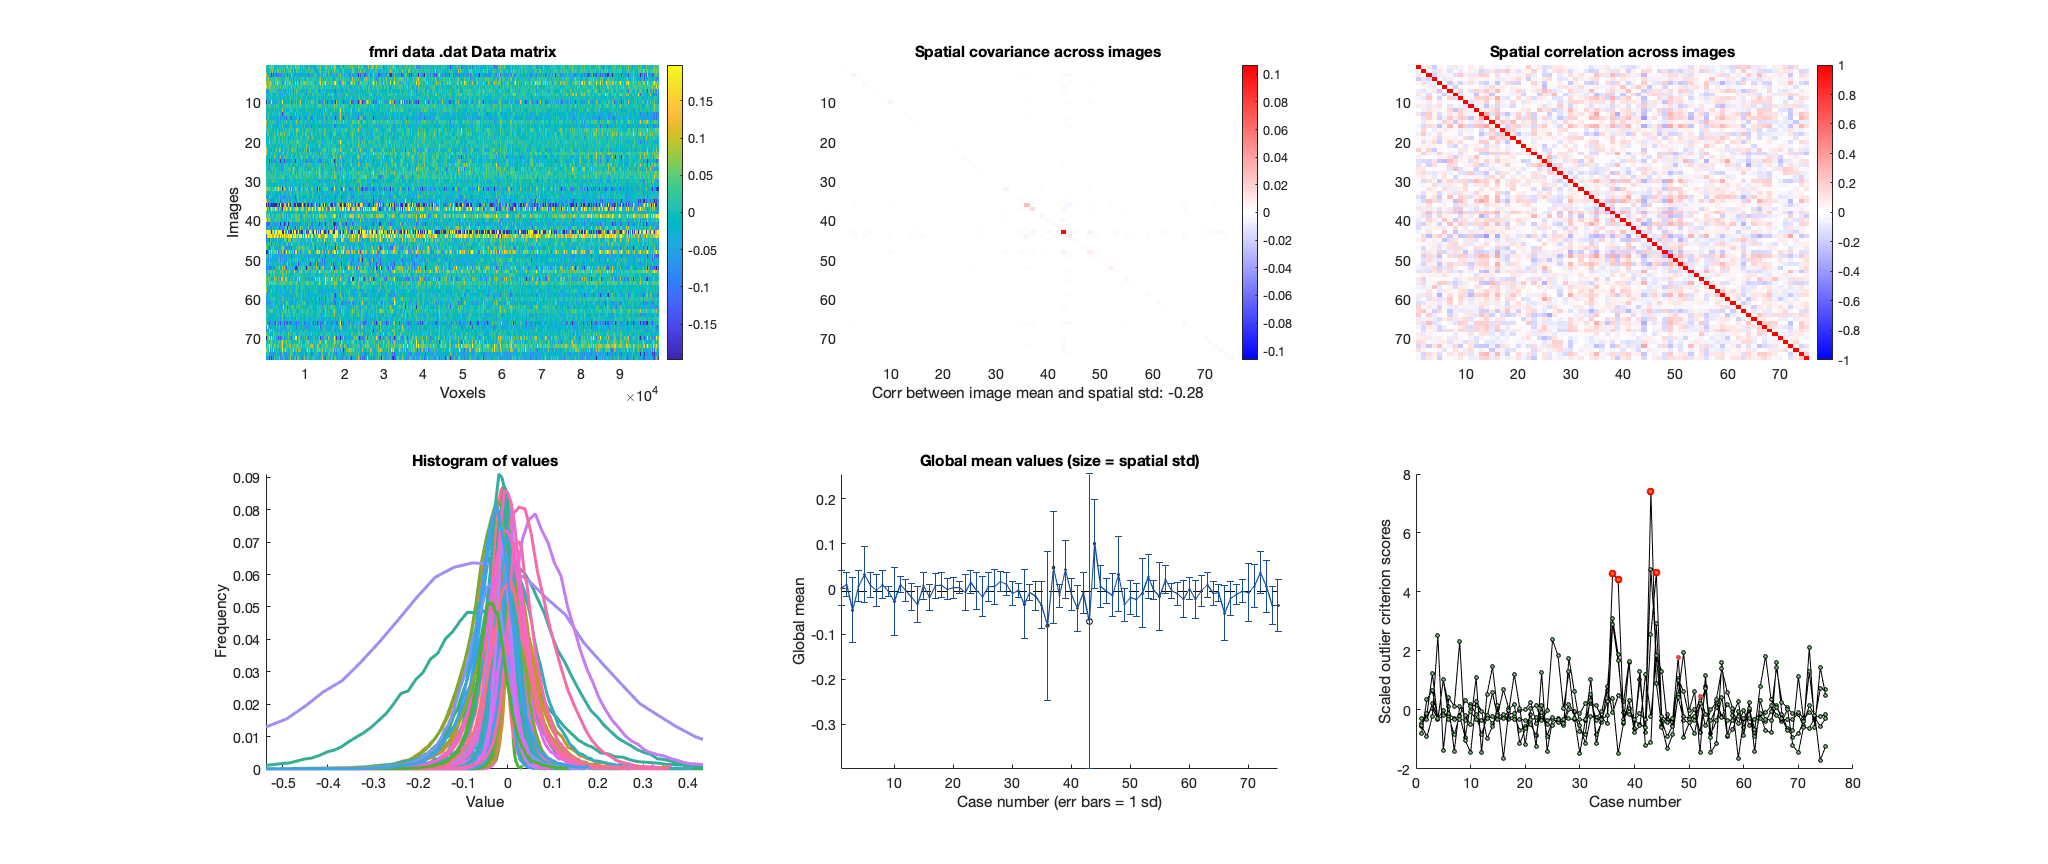

Grouping contiguous voxels:   1 regions


Grouping contiguous voxels:   1 regions


Grouping contiguous voxels:   1 regions


drawnow; snapnow;

[wh_outlier_uncorr, wh_outlier_corr] = plot(con_data_obj);

#### Vicarious x Expectation :: run robfit

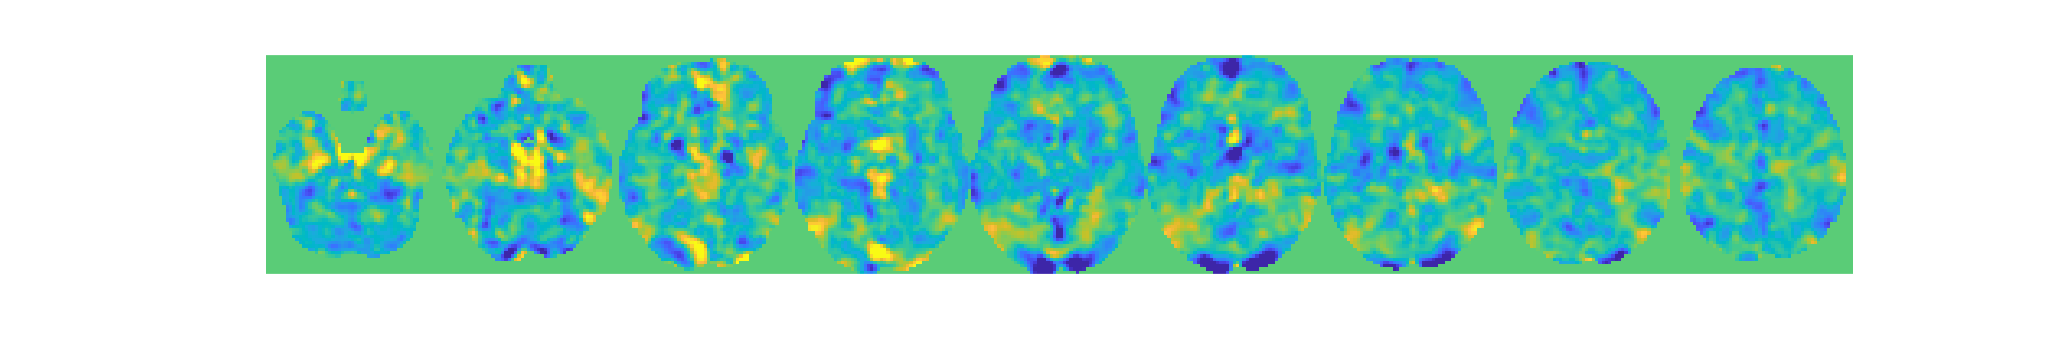

set(gcf,'Visible','on');

figure ('Visible', 'on');
drawnow, snapnow;

#### Vicarious x Expectation :: remove outliers based on plot

con = con_data_obj;
disp(strcat("current length is ", num2str(size(con_data_obj.dat,2))));

current length is 75


%for s = 1:length(wh_outlier_corr)
  %  disp(strcat("-------subject", num2str(s), "------"))
con.dat = con_data_obj.dat(:,~wh_outlier_corr);
con.image_names = con_data_obj.image_names(~wh_outlier_corr,:);
con.fullpath = con_data_obj.fullpath(~wh_outlier_corr,:);
con.files_exist = con_data_obj.files_exist(~wh_outlier_corr,:);
%end
disp(strcat("after removing ", num2str(sum(wh_outlier_corr)), " participants, size is now ",num2str(size(con.dat,2))));

after removing 4 participants, size is now 71


[path,n,e] = fileparts(con_fldr(wh_outlier_corr));
disp(strcat("participants that are outliers:... ", n));

    "participants that are outliers:... sub-0073"    "participants that are outliers:... sub-0074"    "participants that are outliers:... sub-0082"    "participants that are outliers:... sub-0085"



disp(n);

    {'sub-0073'}    {'sub-0074'}    {'sub-0082'}    {'sub-0085'}



#### Vicarious x Expectation :: plot diagnostics, after l2norm

imgs2 = con.rescale('l2norm_images');

#### Vicarious x Expectation :: ttest

t = ttest(imgs2);

One-sample t-test
Calculating t-statistics and p-values


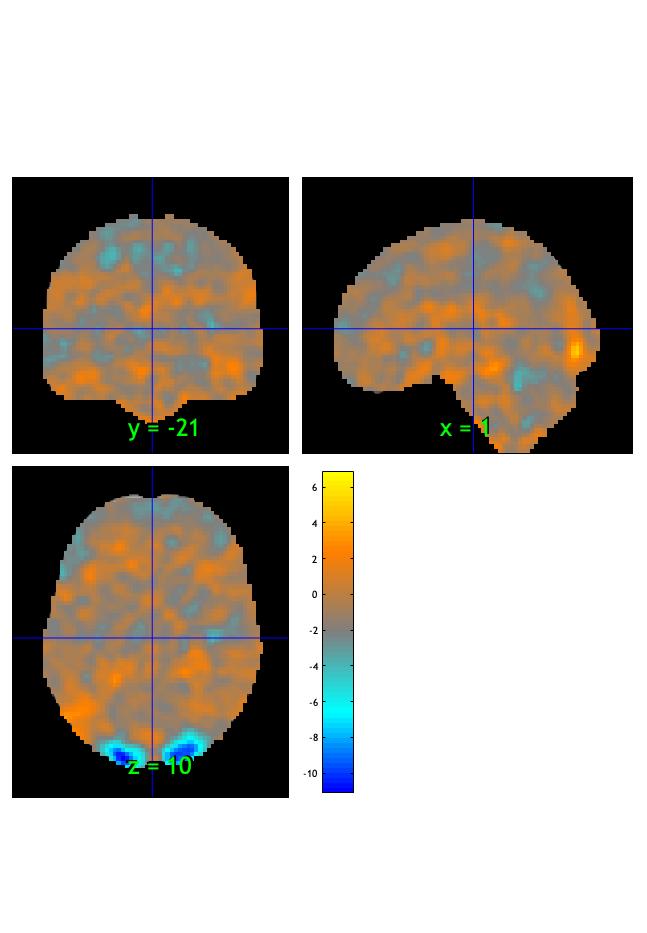

SPM12: spm_check_registration (v7759)              18:50:58 - 12/01/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1


orthviews(t);

drawnow, snapnow;

fdr_t = threshold(t, .05, 'fdr');

Image   1 FDR q < 0.050 threshold is 0.001308

Image   1
 92 contig. clusters, sizes   1 to 495
Positive effect:  76 voxels, min p-value: 0.00000000
Negative effect: 2536 voxels, min p-value: 0.00000000


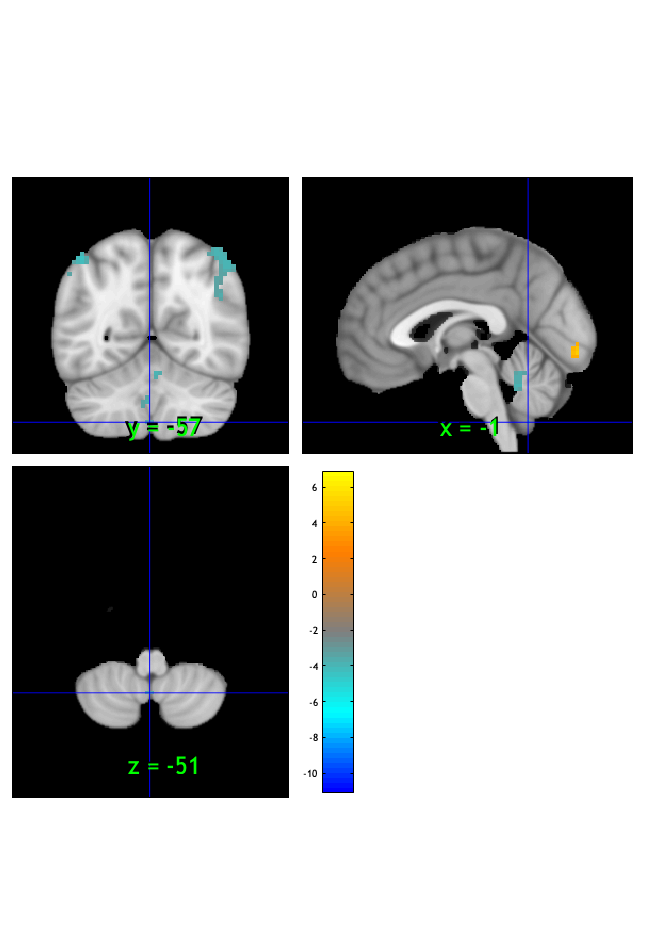

SPM12: spm_check_registration (v7759)              18:50:59 - 12/01/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1


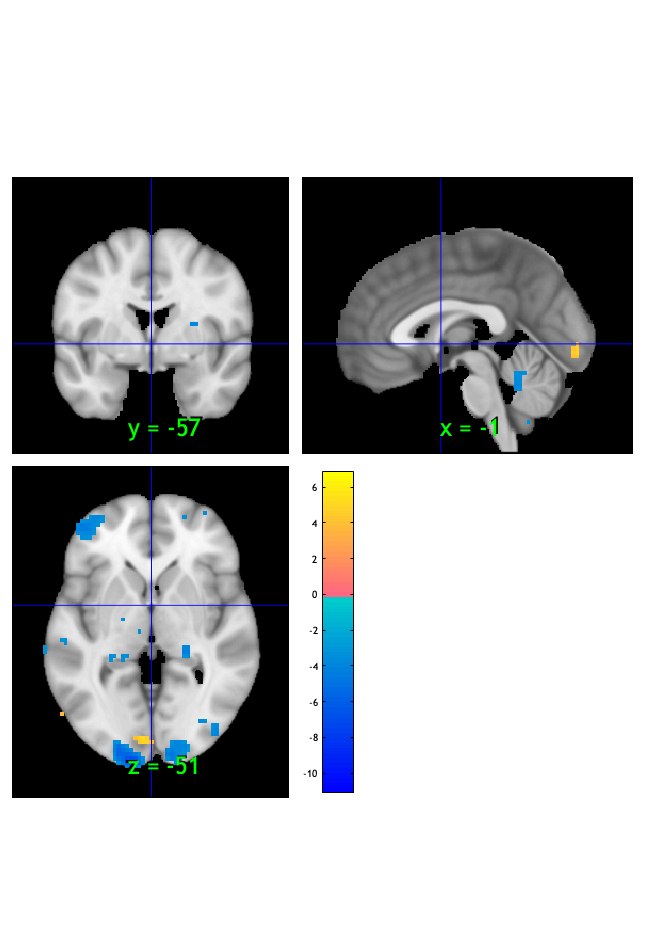

orthviews(fdr_t);

drawnow, snapnow;

create_figure('montage'); axis off;
montage(fdr_t);

Setting up fmridisplay objects


sagittal montage:  32 voxels displayed, 2580 not displayed on these slices


sagittal montage:  14 voxels displayed, 2598 not displayed on these slices


sagittal montage:  19 voxels displayed, 2593 not displayed on these slices


axial montage: 472 voxels displayed, 2140 not displayed on these slices


axial montage: 502 voxels displayed, 2110 not displayed on these slices


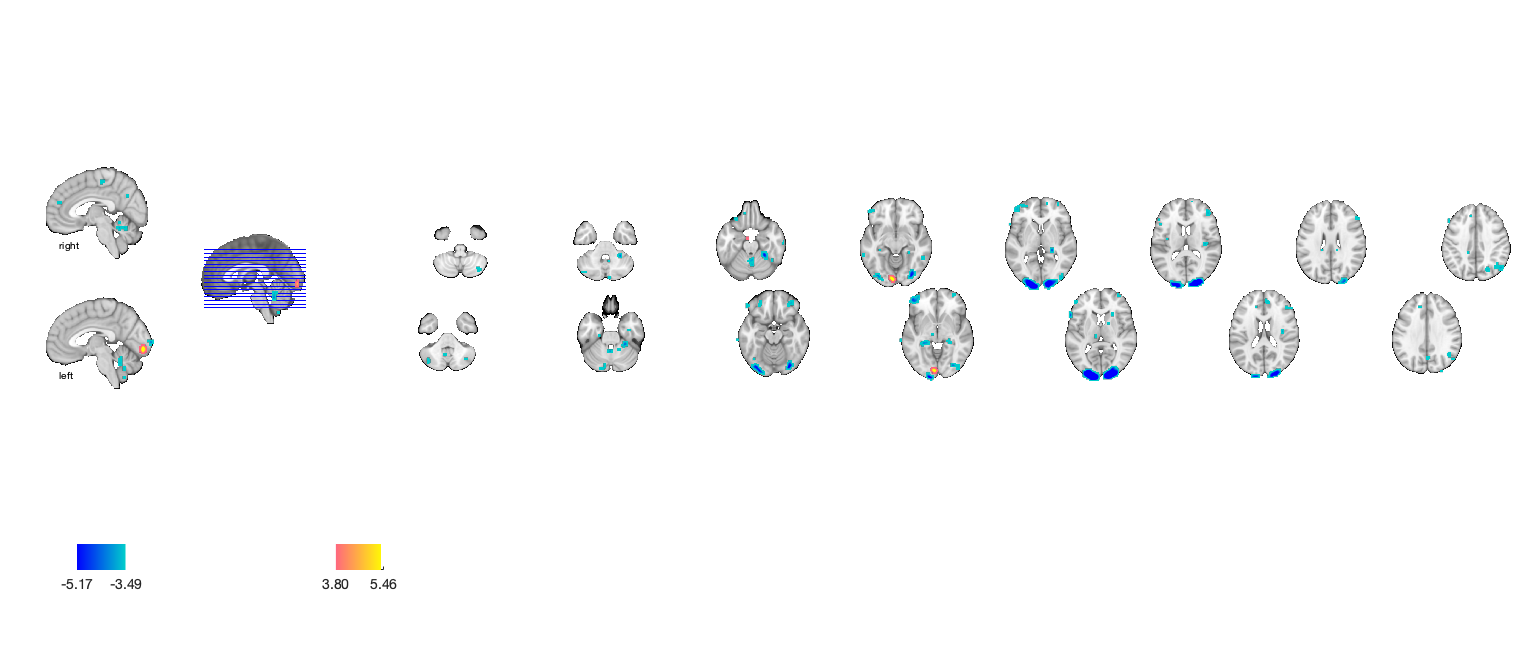

drawnow, snapnow;

#### Vicarious x Expectation :: Neurosynth similarity

[image_by_feature_correlations, top_feature_tables] = neurosynth_feature_labels( mean(imgs2), 'images_are_replicates', false, 'noverbose');

Input image 1
fullpath_was_empty
_____________________________________________________________________
    testr_low       words_low       testr_high      words_high   
    _________    _______________    __________    _______________

    -0.15986     {'retrieval'  }      0.11869     {'body'       }
    -0.15056     {'memory'     }      0.10287     {'stimulation'}
    -0.13398     {'solving'    }     0.093141     {'frequency'  }
    -0.13282     {'episodic'   }     0.083478     {'acoustic'   }
    -0.12877     {'retrieved'  }      0.08188     {'motion'     }
    -0.12283     {'rules'      }     0.078314     {'sequence'   }
    -0.11932     {'engaged'    }     0.077051     {'images'     }
    -0.11826     {'calculation'}     0.072011     {'hand'       }
    -0.11756     {'rule'       }      0.07158     {'movements'  }
    -0.11669     {'colour'     }  

#### Vicarious x Expectation **:: Pattern Phil**

[obj, names] = load_image_set('pain_cog_emo');

Loaded images:
/Users/h/Documents/MATLAB/CanlabCore/CanlabCore/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_pMCC_Pain.nii
/Users/h/Documents/MATLAB/CanlabCore/CanlabCore/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_aMCC_Pain.nii
/Users/h/Documents/MATLAB/CanlabCore/CanlabCore/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_pACC_Pain.nii
/Users/h/Documents/MATLAB/CanlabCore/CanlabCore/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_sgACC_Pain.nii
/Users/h/Documents/MATLAB/CanlabCore/CanlabCore/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_vmPFC_Pain.nii
/Users/h/Documents/MATLAB/CanlabCore/CanlabCore/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_dMFC_Pain.nii
/Users/h/Documents/MATLAB/Can

bpls_wholebrain = get_wh_image(obj, [8 16 24]);
names_wholebrain = names([8 16 24]);
create_figure('Kragel Pain-Cog-Emo maps', 1, 3);

stats = image_similarity_plot(imgs2, 'average', 'mapset', bpls_wholebrain, 'networknames', names_wholebrain, 'nofigure');

Table of correlations Group:1
--------------------------------------
T-test on Fisher's r to Z transformed point-biserial correlations
 	R_avg	T	P	sig	
Pain Wholebrain	0.0086	1.3143	0.1930	0.0000	
Cog Wholebrain	-0.0095	-2.4785	0.0156	1.0000	
Emo Wholebrain	0.0004	0.0544	0.9567	0.0000	
 


axis image

subplot(1, 3, 2)

barplot_columns(stats.r', 'nofigure', 'colors', {[1 .9 0] [.2 .2 1] [1 .2 .2]}, 'names', names_wholebrain)

Col   1: Pain Wholebrain	Col   2: Cog Wholebrain	Col   3: Emo Wholebrain	
---------------------------------------------
Tests of column means against zero
---------------------------------------------
           Name            Mean_Value    Std_Error       T           P        Cohens_d 
    ___________________    __________    _________    ________    ________    _________

    {'Pain Wholebrain'}     0.0086133    0.0065631      1.3124     0.19368      0.15575
    {'Cog Wholebrain' }    -0.0095278    0.0038445     -2.4783    0.015615     -0.29412
    {'Emo Wholebrain' }    0.00036493    0.0068382    0.053366     0.95759    0.0063334



ans = struct with fields:
         fig_han: [1×1 struct]
        axis_han: [1×1 Axes]
        bar_han1: [1×1 Bar]
         bar_han: {[1×1 Bar]  [1×1 Bar]  [1×1 Bar]}
    errorbar_han: {[1×1 ErrorBar]  [1×1 ErrorBar]  [1×1 ErrorBar]}
      point_han1: {71×3 cell}
        text_han: {71×3 cell}
       point_han: {71×3 cell}
    star_handles: [9.0011 10.0011 11.0011]


set(gca, 'FontSize', 14)
ylabel('Pattern similarity (r)');
title('Similarity (r) with patterns')

test_data_obj = resample_space(imgs2, bpls_wholebrain);

clear csim
for i = 1:3

    csim(:, i) = canlab_pattern_similarity(test_data_obj.dat, bpls_wholebrain.dat(:, i), 'cosine_similarity');

end

Number of zero or NaN values within weight mask, by input image:
297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 
Number of zero or NaN values within weight mask, by input image:
297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 


subplot(1, 3, 3)

barplot_columns(csim, 'nofigure', 'colors', {[1 .9 0] [.2 .2 1] [1 .2 .2]}, 'names', names_wholebrain)

Col   1: Pain Wholebrain	Col   2: Cog Wholebrain	Col   3: Emo Wholebrain	
---------------------------------------------
Tests of column means against zero
---------------------------------------------
           Name            Mean_Value    Std_Error       T           P        Cohens_d
    ___________________    __________    _________    _______    _________    ________

    {'Pain Wholebrain'}     0.0077981    0.0063585     1.2264      0.22415     0.14555
    {'Cog Wholebrain' }    -0.0097396    0.0035968    -2.7079    0.0085035    -0.32137
    {'Emo Wholebrain' }     0.0014892     0.006623    0.22486      0.82275    0.026686



ans = struct with fields:
         fig_han: [1×1 struct]
        axis_han: [1×1 Axes]
        bar_han1: [1×1 Bar]
         bar_han: {[1×1 Bar]  [1×1 Bar]  [1×1 Bar]}
    errorbar_han: {[1×1 ErrorBar]  [1×1 ErrorBar]  [1×1 ErrorBar]}
      point_han1: {71×3 cell}
        text_han: {71×3 cell}
       point_han: {71×3 cell}
    star_handles: [12.0011 13.0011 14.0011]


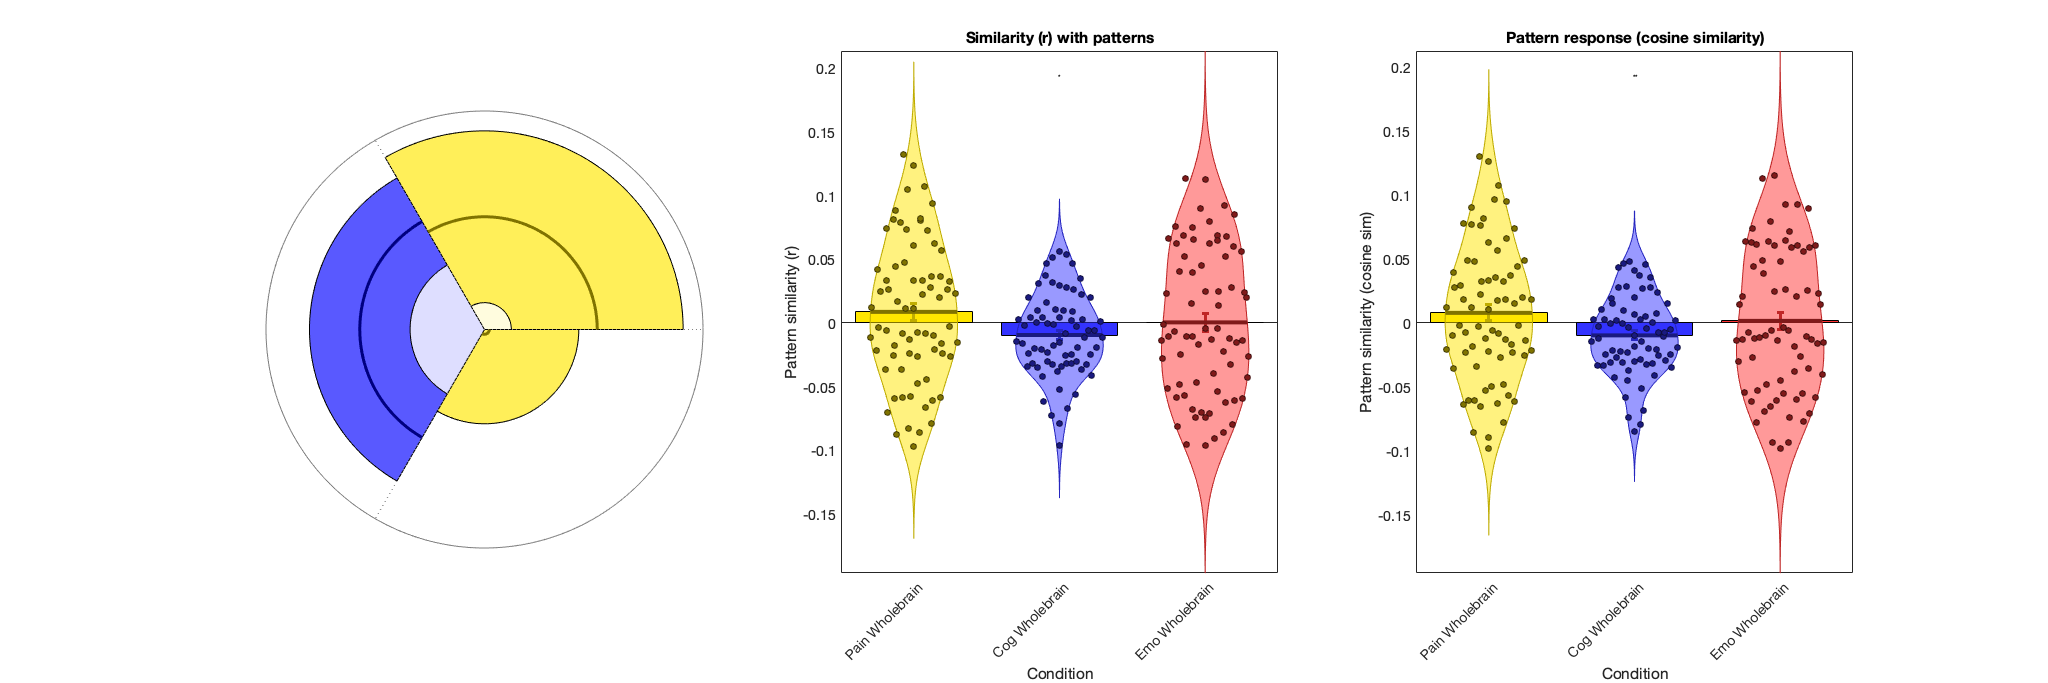

set(gca, 'FontSize', 14)
ylabel('Pattern similarity (cosine sim)');
title('Pattern response (cosine similarity)')

# Cognitive modulated w/ expectation ratings (dummy coded; cognitiveXexpectation > rest)

#### Cognitive x Expectation :: load dataset

clear all; close all;
mount_dir = '/Volumes/spacetop_projects_cue/analysis/fmri/spm/univariate/model02_CESeO/1stLevel';
con_list = dir(fullfile(mount_dir, '*/con_0021.nii'));
spm('Defaults','fMRI');
con_fldr = {con_list.folder}; fname = {con_list.name};
con_files = strcat(con_fldr,'/', fname)';
con_data_obj = fmri_data(con_files);

Using default mask: /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/brainmask_canlab.nii
Direct calls to spm_defauts are deprecated.
Please use spm('Defaults',modality) or spm_get_defaults instead.


sampleto = '/Volumes/spacetop_projects_cue/analysis/fmri/spm/univariate/model02_CESeO/1stLevel/sub-0014/con_0021.nii'

loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 29951100 bytes
Loading image number:    75
Elapsed time is 10.385014 seconds.
Image names entered, but fullpath attribute is empty. Getting path info.
Number of unique values in dataset: 7213189  Bit rate: 22.78 bits


contrast_name = {'cue_P', 'cue_V', 'cue_C', 'cue_G',...
    'stim_P', 'stim_V', 'stim_C', 'stim_G',...
    'stimXexpect_P', 'stimXexpect_V', 'stimXexpect_C',...
    'motor', ...
    'simple_cue_P', 'simple_cue_V', 'simple_cue_C', ...
    'simple_stim_P', 'simple_stim_V', 'simple_stim_C',...
    'simple_stimXexpect_P', 'simple_stimXexpect_V', 'simple_stimXexpect_C'};


#### Cognitive x Expectation :: `check data coverage`

m = mean(con_data_obj);
m.dat = sum(~isnan(con_data_obj.dat) & con_data_obj.dat ~= 0, 2);
orthviews(m, 'trans'); % display

SPM12: spm_check_registration (v7759)              18:53:36 - 12/01/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1


Grouping contiguous voxels:   1 regions


#### Cognitive x Expectation :: Plot diagnostics, before l2norm

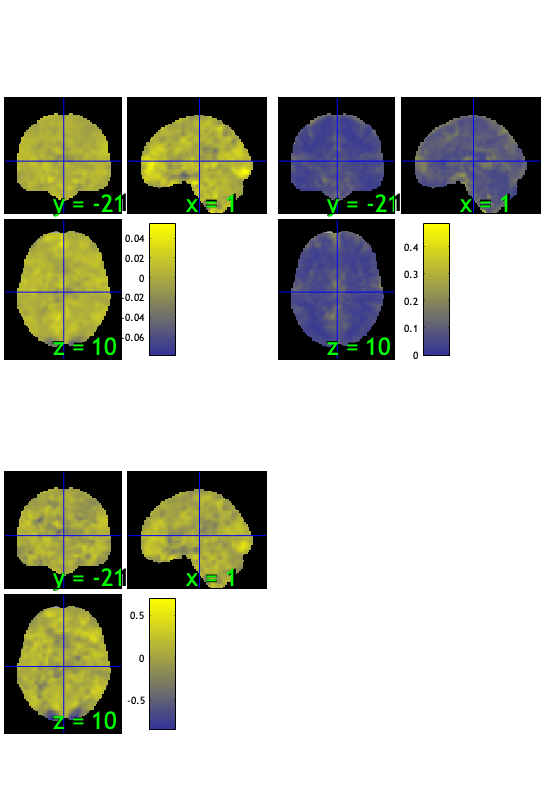

______________________________________________________________
Outlier analysis
______________________________________________________________
global mean | global mean to var | spatial MAD | Missing values |   0 images 


Retained 3 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 20.00%
Expected 3.75 outside 95% ellipsoid, found   5

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 3 images		Cases 3 41 75 
Uncorrected: 5 images		Cases 3 41 55 70 75 

Retained 11 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 54.67%
Expected 3.75 outside 95% ellipsoid, found   1

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 0 images		Cases  
Uncorrected: 1 images		Cases 26 

Mahalanobis (cov and corr, q<0.05 corrected):
  3 images 
                               Outlier_count    Percentage
                               

SPM12: spm_check_registration (v7759)              18:54:17 - 12/01/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1
 (all)  

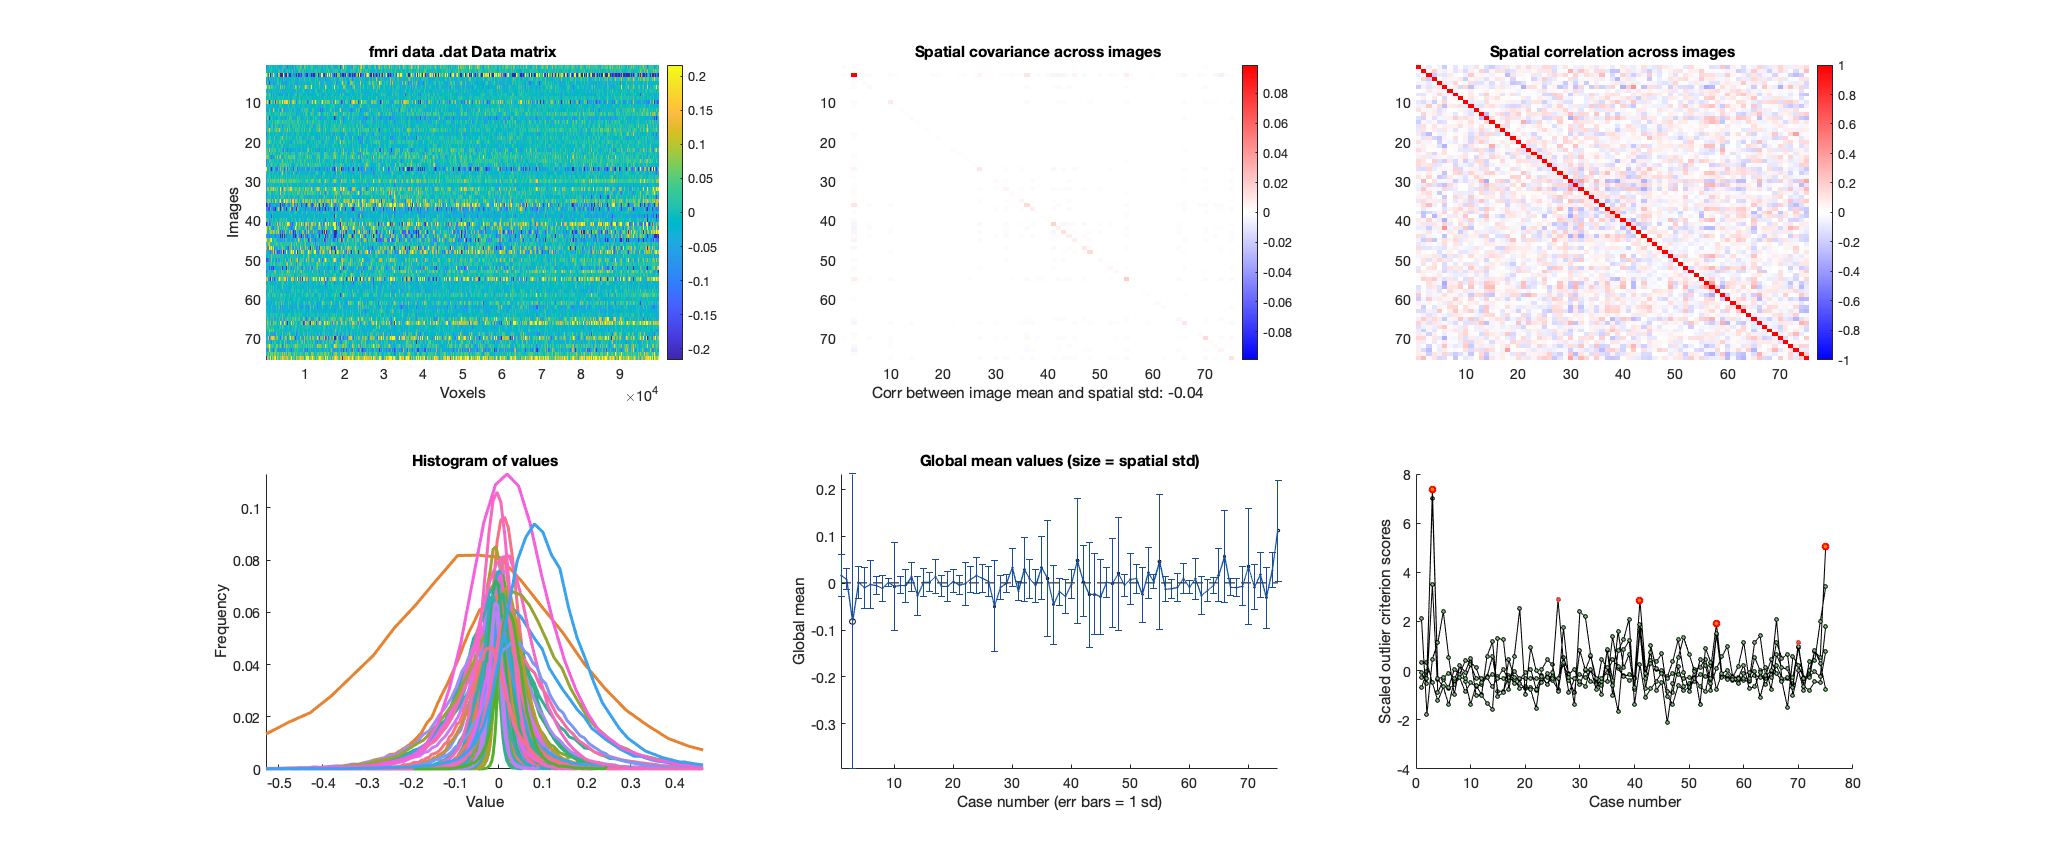

Grouping contiguous voxels:   1 regions


Grouping contiguous voxels:   1 regions


Grouping contiguous voxels:   1 regions


drawnow; snapnow;

[wh_outlier_uncorr, wh_outlier_corr] = plot(con_data_obj);

#### Cognitive x Expectation :: run robfit

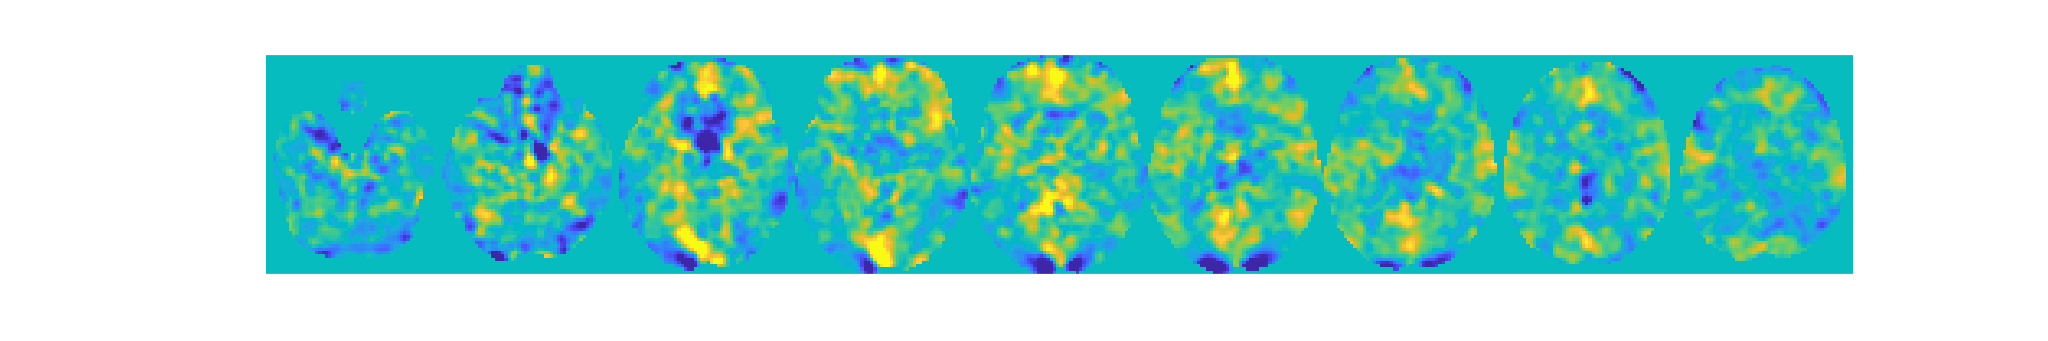

set(gcf,'Visible','on');

figure ('Visible', 'on');
drawnow, snapnow;

#### Cognitive x Expectation :: remove outliers based on plot

con = con_data_obj;
disp(strcat("current length is ", num2str(size(con_data_obj.dat,2))));

current length is 75


%for s = 1:length(wh_outlier_corr)
   % disp(strcat("-------subject", num2str(s), "------"))
con.dat = con_data_obj.dat(:,~wh_outlier_corr);
con.image_names = con_data_obj.image_names(~wh_outlier_corr,:);
con.fullpath = con_data_obj.fullpath(~wh_outlier_corr,:);
con.files_exist = con_data_obj.files_exist(~wh_outlier_corr,:);
%end
disp(strcat("after removing ", num2str(sum(wh_outlier_corr)), " participants, size is now ",num2str(size(con.dat,2))));

after removing 4 participants, size is now 71


[path,n,e] = fileparts(con_fldr(wh_outlier_corr));
disp(strcat("participants that are outliers:... ", n));

    "participants that are outliers:... sub-0016"    "participants that are outliers:... sub-0079"    "participants that are outliers:... sub-0100"    "participants that are outliers:... sub-0133"



disp(n);

    {'sub-0016'}    {'sub-0079'}    {'sub-0100'}    {'sub-0133'}



#### Cognitive x Expectation:: plot diagnostics, after l2norm

imgs2 = con.rescale('l2norm_images');

#### Cognitive x Expectation :: ttest

t = ttest(imgs2);

One-sample t-test
Calculating t-statistics and p-values


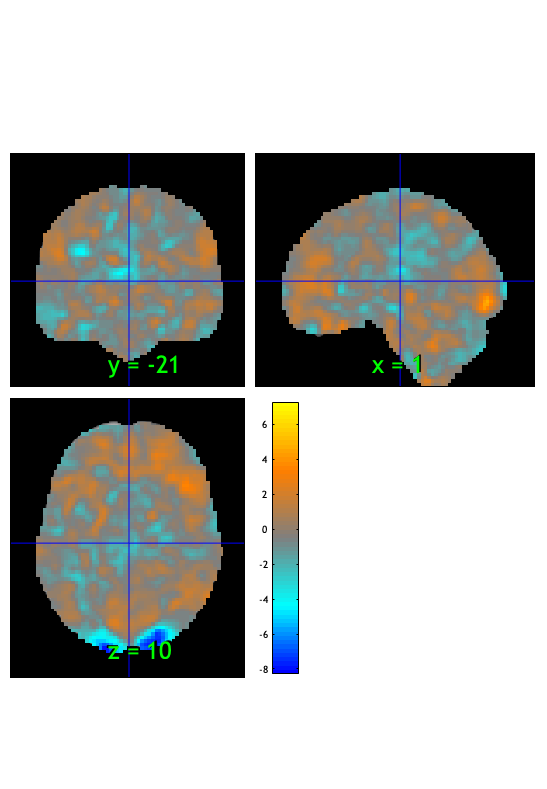

SPM12: spm_check_registration (v7759)              18:54:24 - 12/01/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1


orthviews(t);

drawnow, snapnow;

fdr_t = threshold(t, .05, 'fdr');

Image   1 FDR q < 0.050 threshold is 0.000335

Image   1
 15 contig. clusters, sizes   1 to 271
Positive effect: 113 voxels, min p-value: 0.00000000
Negative effect: 559 voxels, min p-value: 0.00000000


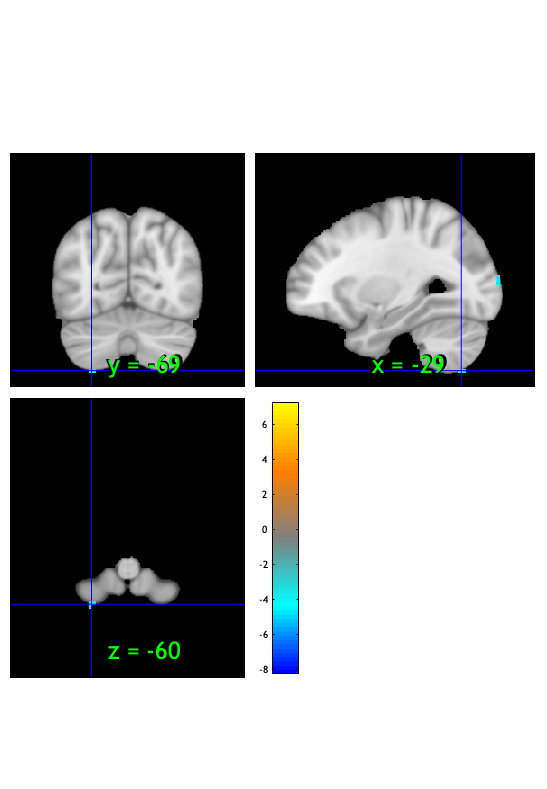

SPM12: spm_check_registration (v7759)              18:54:25 - 12/01/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1


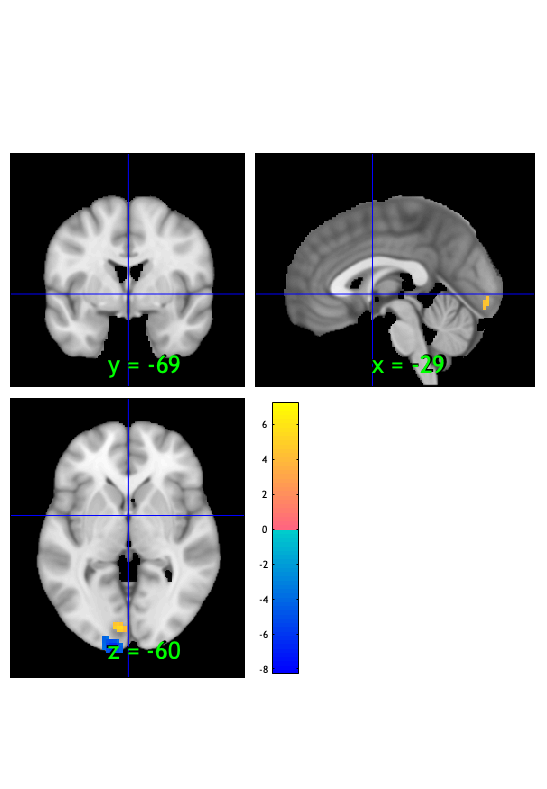

orthviews(fdr_t);

drawnow, snapnow;

create_figure('montage'); axis off;
montage(fdr_t);

Setting up fmridisplay objects


sagittal montage:  22 voxels displayed, 650 not displayed on these slices


sagittal montage:   1 voxels displayed, 671 not displayed on these slices


sagittal montage:   6 voxels displayed, 666 not displayed on these slices


axial montage: 159 voxels displayed, 513 not displayed on these slices


axial montage: 150 voxels displayed, 522 not displayed on these slices


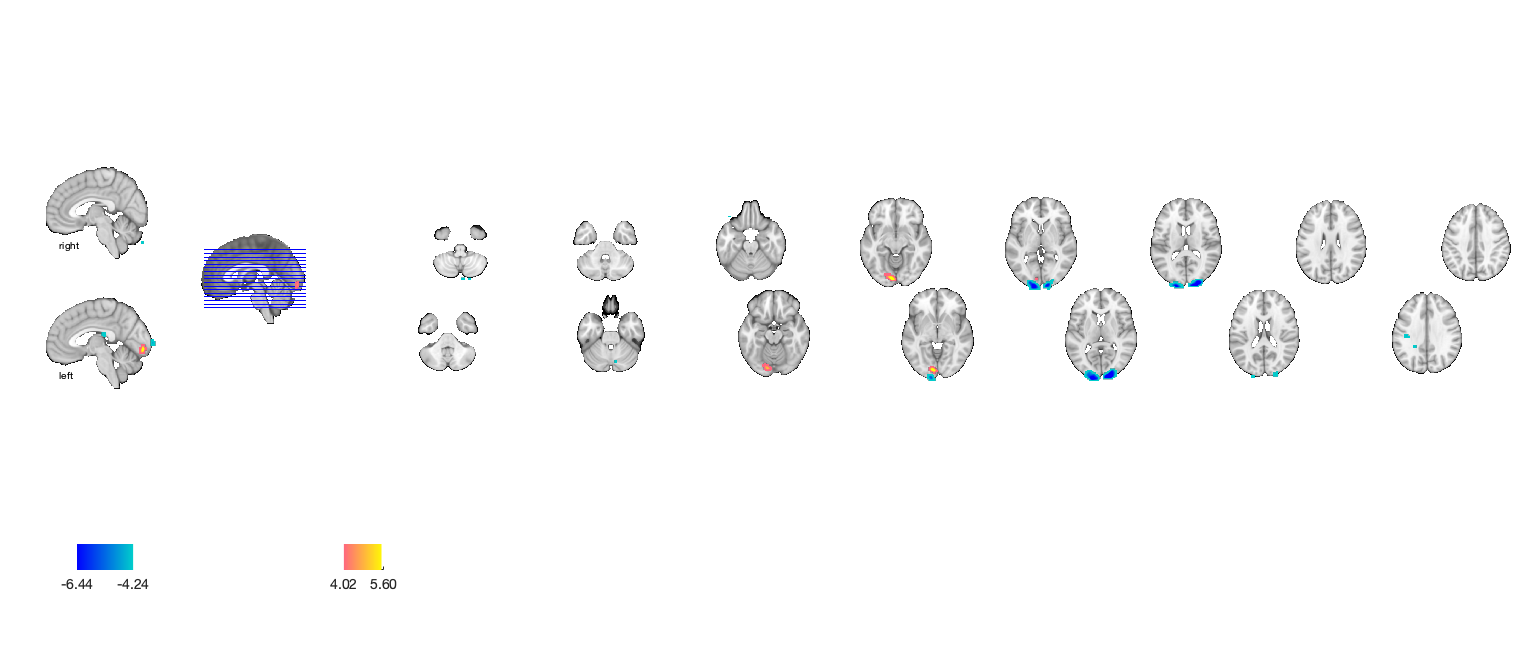

drawnow, snapnow;

#### Cognitive x Expectation :: Neurosynth similarity

[image_by_feature_correlations, top_feature_tables] = neurosynth_feature_labels( mean(imgs2), 'images_are_replicates', false, 'noverbose');

Input image 1
fullpath_was_empty
_____________________________________________________________________
    testr_low       words_low        testr_high        words_high    
    _________    ________________    __________    __________________

    -0.063503    {'associations'}     0.097361     {'empathy'       }
    -0.061685    {'frequency'   }     0.095097     {'counting'      }
    -0.059556    {'visuospatial'}     0.091249     {'gonogo'        }
    -0.057487    {'pair'        }     0.089328     {'go'            }
    -0.055975    {'adaptation'  }     0.087797     {'feelings'      }
    -0.054101    {'pairs'       }     0.083917     {'tom'           }
    -0.049129    {'priming'     }     0.082425     {'nogo'          }
    -0.046734    {'recognition' }     0.077818     {'empathic'      }
    -0.046251    {'identity'    }     0.076653     {'unpleas

#### Cognitive x Expectation **:: Pattern Phil**

[obj, names] = load_image_set('pain_cog_emo');

Loaded images:
/Users/h/Documents/MATLAB/CanlabCore/CanlabCore/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_pMCC_Pain.nii
/Users/h/Documents/MATLAB/CanlabCore/CanlabCore/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_aMCC_Pain.nii
/Users/h/Documents/MATLAB/CanlabCore/CanlabCore/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_pACC_Pain.nii
/Users/h/Documents/MATLAB/CanlabCore/CanlabCore/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_sgACC_Pain.nii
/Users/h/Documents/MATLAB/CanlabCore/CanlabCore/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_vmPFC_Pain.nii
/Users/h/Documents/MATLAB/CanlabCore/CanlabCore/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_dMFC_Pain.nii
/Users/h/Documents/MATLAB/Can

bpls_wholebrain = get_wh_image(obj, [8 16 24]);
names_wholebrain = names([8 16 24]);
create_figure('Kragel Pain-Cog-Emo maps', 1, 3);

stats = image_similarity_plot(imgs2, 'average', 'mapset', bpls_wholebrain, 'networknames', names_wholebrain, 'nofigure');

Table of correlations Group:1
--------------------------------------
T-test on Fisher's r to Z transformed point-biserial correlations
 	R_avg	T	P	sig	
Pain Wholebrain	0.0016	0.2361	0.8140	0.0000	
Cog Wholebrain	-0.0027	-0.5382	0.5921	0.0000	
Emo Wholebrain	0.0009	0.1139	0.9096	0.0000	
 


axis image

subplot(1, 3, 2)

barplot_columns(stats.r', 'nofigure', 'colors', {[1 .9 0] [.2 .2 1] [1 .2 .2]}, 'names', names_wholebrain)

Col   1: Pain Wholebrain	Col   2: Cog Wholebrain	Col   3: Emo Wholebrain	
---------------------------------------------
Tests of column means against zero
---------------------------------------------
           Name            Mean_Value    Std_Error       T           P       Cohens_d 
    ___________________    __________    _________    ________    _______    _________

    {'Pain Wholebrain'}      0.001583    0.0067793     0.23351    0.81604     0.027713
    {'Cog Wholebrain' }    -0.0026979    0.0050104    -0.53846    0.59197    -0.063903
    {'Emo Wholebrain' }    0.00091326    0.0077085     0.11847    0.90603      0.01406



ans = struct with fields:
         fig_han: [1×1 struct]
        axis_han: [1×1 Axes]
        bar_han1: [1×1 Bar]
         bar_han: {[1×1 Bar]  [1×1 Bar]  [1×1 Bar]}
    errorbar_han: {[1×1 ErrorBar]  [1×1 ErrorBar]  [1×1 ErrorBar]}
      point_han1: {71×3 cell}
        text_han: {71×3 cell}
       point_han: {71×3 cell}
    star_handles: [9.0012 10.0012 11.0012]


set(gca, 'FontSize', 14)
ylabel('Pattern similarity (r)');
title('Similarity (r) with patterns')

test_data_obj = resample_space(imgs2, bpls_wholebrain);

clear csim
for i = 1:3

    csim(:, i) = canlab_pattern_similarity(test_data_obj.dat, bpls_wholebrain.dat(:, i), 'cosine_similarity');

end

Number of zero or NaN values within weight mask, by input image:
297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 
Number of zero or NaN values within weight mask, by input image:
297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 


subplot(1, 3, 3)

barplot_columns(csim, 'nofigure', 'colors', {[1 .9 0] [.2 .2 1] [1 .2 .2]}, 'names', names_wholebrain)

Col   1: Pain Wholebrain	Col   2: Cog Wholebrain	Col   3: Emo Wholebrain	
---------------------------------------------
Tests of column means against zero
---------------------------------------------
           Name            Mean_Value    Std_Error       T           P       Cohens_d 
    ___________________    __________    _________    ________    _______    _________

    {'Pain Wholebrain'}    0.00072591    0.0065704     0.11048    0.91234     0.013112
    {'Cog Wholebrain' }    -0.0023482    0.0047767    -0.49159    0.62455    -0.058341
    {'Emo Wholebrain' }     0.0014649    0.0075649     0.19365    0.84701     0.022982



ans = struct with fields:
         fig_han: [1×1 struct]
        axis_han: [1×1 Axes]
        bar_han1: [1×1 Bar]
         bar_han: {[1×1 Bar]  [1×1 Bar]  [1×1 Bar]}
    errorbar_han: {[1×1 ErrorBar]  [1×1 ErrorBar]  [1×1 ErrorBar]}
      point_han1: {71×3 cell}
        text_han: {71×3 cell}
       point_han: {71×3 cell}
    star_handles: [12.0012 13.0012 14.0012]


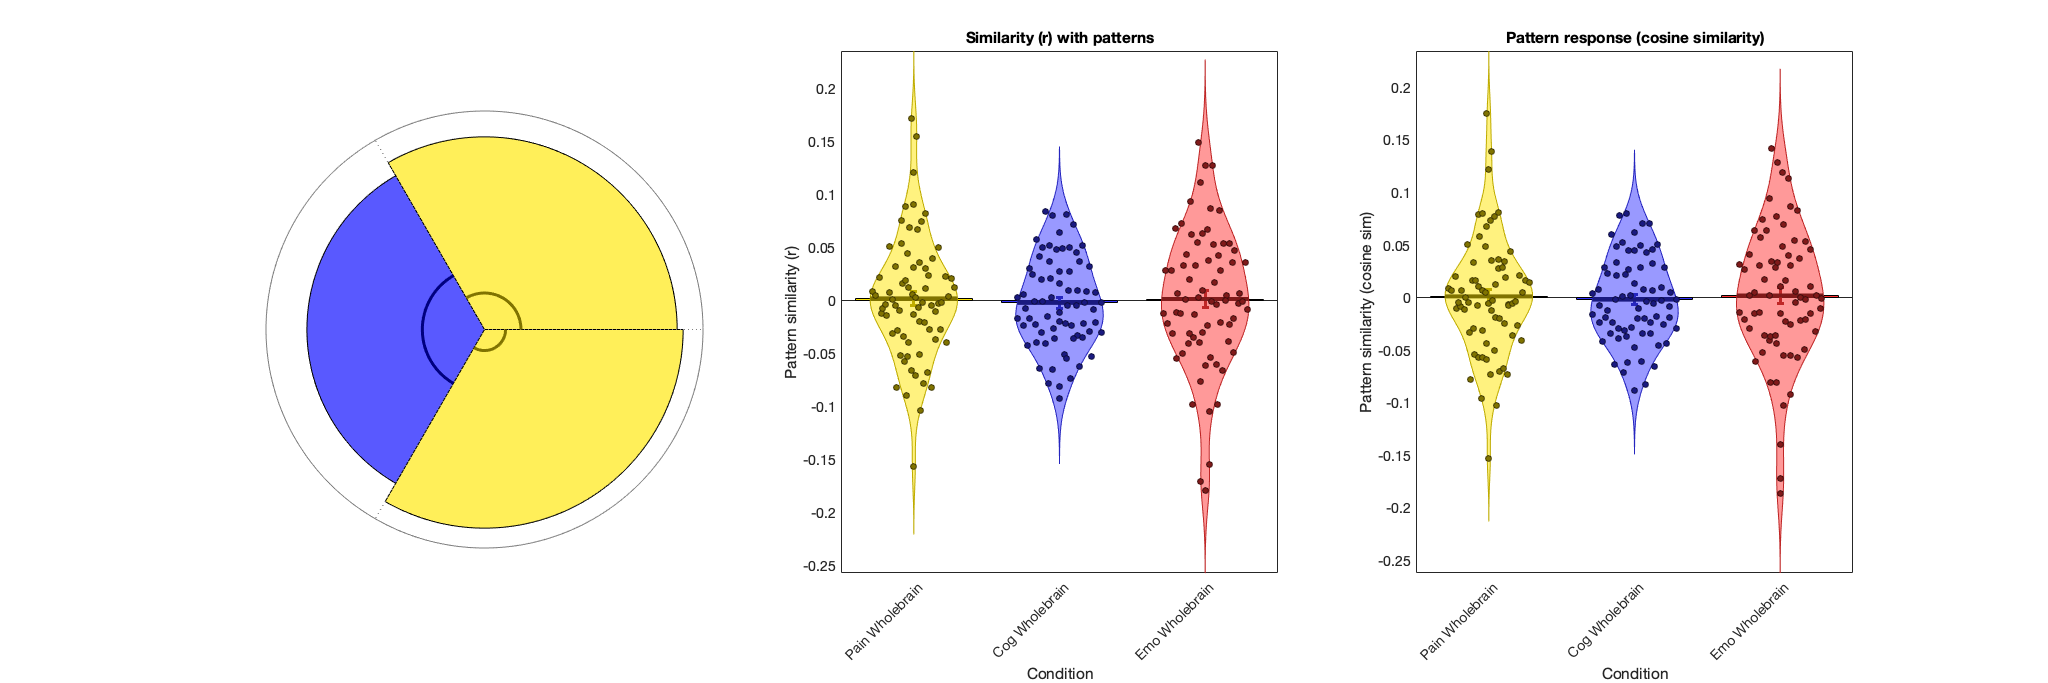

set(gca, 'FontSize', 14)
ylabel('Pattern similarity (cosine sim)');
title('Pattern response (cosine similarity)')

drawnow, snapnow;

% save html
pubdir = pwd;
pubfilename = 's03_PVC_stim_dummy_ROI.mlx';

p = struct('useNewFigure', false, 'maxHeight', 800, 'maxWidth', 800, ...
  'format', 'html', 'outputDir', pubdir, ...
  'showCode', true, 'stylesheet', which('mxdom2simplehtml_CANlab.xsl'));
htmlfile = publish(pubfilename, p);